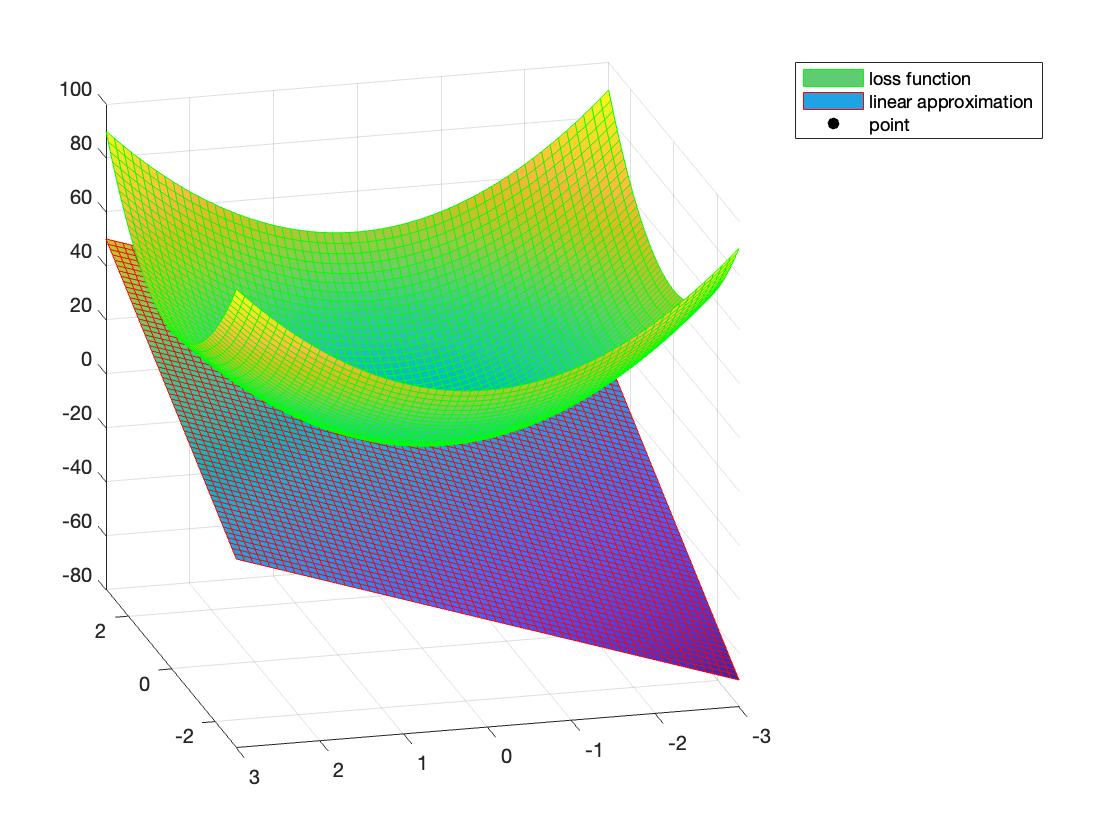

clear 
close all

x = -3:1e-1:3;
y = x;
[X,Y] = meshgrid(x);
% loss function
f = @(x, y) 5.*x.^2+5.*y.^2;
% graident point
x0 = [1; 1];
% graident function
g1 = @(x, y) 10.*x;
g2 = @(x, y) 10.*y;
% linear approximation function
f1 = @(deltax, deltay) f(x0(1), x0(2)) + (deltax-x0(1)).*g1(x0(1), x0(2)) + (deltay-x0(2)).*g2(x0(1), x0(2));

s1 = surf(X, Y, f(X,Y));
s1.EdgeColor = [0,1,0];
hold on
s2 = surf(X, Y, f1(X,Y));
s2.EdgeColor = [1,0,0];
hold on
s3 = scatter3(x0(1), x0(2), f(x0(1), x0(2)), 'filled', "MarkerFaceColor",[0,0,0]);
s3.SizeData = 1000;
legend('loss function', 'linear approximation', 'point')
hold off